**Co**ntinuation of **S**olution **T**orus **A**pp**R**oximations

[Engineering Dynamics Group, Institute for Mechanics, University of Kassel, Germany](https://www.uni-kassel.de/maschinenbau/institute/mechanik/fachgebiete/technische-dynamik/startseite)

# Tutorial: Postprocessing Function `solplot`

## Welcome to the CoSTAR Tutorials!

In this tutorial, we will look at the postprocessing functions `solplot` and how to use it. `solplot` is used to plot individual solutions in different *solution spaces*. It also returns the plotted data points.

Apart from `solplot`, there are also the postprocessing methods `contplot` for creating continuation (bifurcation) diagrams (it also returns the plotted data points) and `solget` for obtaining solution data without plotting, which can be further used for individual purposes. To learn about `contplot` and `solget`, please see the corresponding tutorials.

Of course, we need a solution computed by CoSTAR before we can use the postprocessing functions, so we start with a continuation in order to have a set of solutions at hand. After that, we will have a detailed look at `solplot`.

## Computing solutions to work with

In this tutorial, we use the periodically forced *Duffing* oscillator $x^{\prime\prime} + 2Dx{\prime} + x + \kappa x^3 = g \cos (\eta \tau)$ as an example. The continuation parameter $\mu$ will be the excitation frequency $\eta$ and we will use the shooting method to approximate the solutions.

Before we can use CoSTAR, we need to add the main CoSTAR folder (and all subfolders) to MATLAB's search path. Assuming you are running this script within the *Tutorials* subfolder of CoSTAR, this is done by:

% addpath(genpath('..\'))           % genpath() generates a search path containing all subfolders

(Note: The command above is set as comment in order to prevent unwanted folders to be added to MATLAB's search path in case that the current path is not the *Tutorials* subfolder.)

Now we are set to perform a continuation of the periodically forced *Duffing* oscillator using the shooting method. The following code is taken from *Example_PS_SHM *and not explained any further at this point. If you are new to CoSTAR, it is advised to go through the corresponding example within the tutorial on periodic solutions approximated by the shooting method (see *Tutorial_PS_SHM*, chapter 1) before continuing with this tutorial.


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          4           0.0292105                           0.171              1
     1          8           3.649e-18       0.170911         1.42e-09              1

Equation solved. The sum of squared function values, r = 3.648999e-18, is less than
sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of r,
1.423941e-09, is less than options.OptimalityTolerance = 1.000000e-06.

-------------------------------------------------------
--------------- Initial solution found! ---------------
-------------------------------------------------------
Iter: 2 -- mu = 0.1100 -- stepwidth = 0.1000
Iter: 3 -- mu = 0.1642 -- stepwidth = 0.0500
Iter: 4 -- mu = 0.1729 -- stepwidth = 0.0250
Iter: 5 -- mu = 0.1903 -- stepwidth =

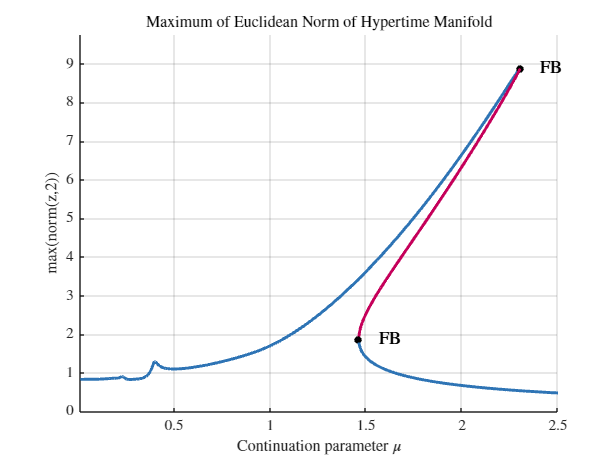

clear variables; clc; close all;                    % clear workspace; clear command window; close all figures

% Parameters
D = 0.05;     kappa = 0.3;     g = 1;               % Parameters needed for the Duffing differential equation
mu_limit = [0.01, 2.5];                             % Limits of the continuation        
eta0 = mu_limit(1);                                 % Value of continuation parameter at start of continuation
param = {kappa, D, eta0, g};                        % Parameter array
active_parameter = 3;                               % Location of continuation parameter within the array
IC = [1; 0];                                        % Initial condition (point in state space) for fsolve

% Functions
non_auto_freq = @(mu) mu;                           % Non-autonomous excitation frequency
Fcn =  @(t,z,param) duffing_ap(t,z,param);          % Right-hand side of dz/dtau = f(tau,z,kappa,D,eta,g)

% Options
options.system = costaropts('order',1,'dim',2,'rhs',Fcn,'param',param,'info','continuation of Duffing equation');   % Properties of the system
options.opt_sol = costaropts('sol_type','periodic','approx_method','shooting','cont','on','stability','on', ...     % Properties of the solution
                             'non_auto_freq',non_auto_freq,'act_param',active_parameter);                           % Properties of the solution
options.opt_init = costaropts('ic',IC);                                                                             % Property for initial solution
options.opt_approx_method = costaropts('solver','ode45');                                                           % Properties of approximation method
options.opt_cont = costaropts('mu_limit',mu_limit);                                                                 % Properties for continuation

% Continuation
[S,DYN] = costar(options);                          % CoSTAR is called by costar(options)

Alright, now we have enough solutions to work with and we can begin with the actual tutorial on the postprocessing method `solplot`.

# `solplot`

The postprocessing function `solplot` is used to display individual solutions in different *solution spaces*. In particular, four different solution spaces are available:

- ***Time*****:**              The solution is plotted with respect to time $t$

- ***Hypertime*****:**     The solution is displayed with respect to hypertime $\theta$ (periodic case) or $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$ (quasi-periodic case)

- ***Trajectory*****:   **  The trajectory of a solution is plotted in state space or in a corresponding subspace (2D or 3D respectively)

- ***Frequency*****:**    The frequency content of a solution is displayed

In the following, we will focus on periodic (1D manifolds) and quasi-periodic (2D manifolds) solutions. Although equilibrium solutions (0D manifolds) could theoretically be depicted in the available solution spaces as well, it does not really make sense since the resulting plots would be very trivial. That is why the use of solplot for equilibrium solutions is in fact disabled in CoSTAR. 

## General syntax

`solplot` is used in the following way:

### **Input arguments**

- `DYN`**:** `DynamicalSystem` object returned by the `costar` function. Must correspond to `Solution` object `S`, which is also returned by the `costar` function.

- `solplot_options`**:** Structure defining the necessary options. Must be created using the `costaropts` function. In case of any invalid entry, the CoSTAR *Gatekeeper* will throw an error.

### **Output arguments**

The four output arguments depend on the selected solution space in which the solution is displayed. 

The specific meaning of the ordinate values and of the depicted trajectory(s) in state space depend on the requested quantity to plot, which is defined via the options field `'zaxis'` (as well as `'xaxis'` and potentially `'yaxis'` for *trajectory* plots). For instance, the ordinate values may represent the first state variable $z_1$ or, in case of a 2D trajectory plot, the state variables $z_1$ and $z_2$. Further explanations of the mentioned options fields can be found in the subsection **Mandatory fields** below.

The individual array sizes of the different outputs depend on the solution space, the solution type (periodic or quasi-periodic), the requested quantity to plot, the number of different solutions to plot and the desired resolution of the solutions to plot. An overview on the possible array sizes is given by the table below, where

- `n_sol` is the number of different solutions (in context of a continuation) to plot. The number corresponds to the field `'index'` via `n_sol = numel(options.index)` (further explanations of `'index'` can be found in the subsection **Optional fields** below).

- `dim_eval_z` corresponds to the dimension of the evaluated state vector $\mathbf z$ and therefore it corresponds to the number of plots (the number of plotted lines and hypertime surfaces) for each solution (in context of a continuation). It is determined by the value of the options field `'zaxis'` (see subsection **Mandatory fields** below). In case of `options.zaxis = 'all'`, `dim_eval_z` is equal to the dimension $d$ of the system since the solutions of all state variables are plotted. In all other cases, i.e. `options.zaxis = 'euclidean'` or `options.zaxis` is set as *function handle*, `dim_eval_z` equals 1 since these options map the $d$ elements of the state vector $\mathbf z$ to an output of dimension $d^* = 1$ $(\mathbb R^d \rightarrow \mathbb R)$.

- `res` is the resolution, i.e. the number of data points (along the underlying time or hypertime domain) which are used for a solution plot. `res` can be set via the options field `'resolution'` (see subsection **Optional fields** below).

The structure of the output arrays is overall fairly similar and can easily be understood by the table and explanation above.

- All array dimensions of size `res` correspond to time $t$ or hypertime $\theta$. For plots in *quasi-periodic hypertime* solution space, there are two array dimensions `res_1` and `res_2` since the solutions are parametrized in hypertime coordinates $\theta_1$ and $\theta_2$. Naturally, `res_1` corresponds to hypertime $\theta_1$ and `res_2` corresponds to hypertime $\theta_2$. 

- For *frequency* solution space, the array dimensions of size `res/2` correspond to the angular frequency $\omega$ (in context of the frequency content of a solution) as a Fast-Fourier-Transformation (FFT) is carried out when plotting in *frequency* solution space. Here, `res` must be an even positive integer.

- All array dimensions of size `dim_eval_z` either correspond to the state variables of a system (in case of `options.zaxis = 'all')` or they correspond to the Euclidean norm $\Vert \mathbf z \Vert$ of all state variables (in case of `options.zaxis = 'euclidean')` or they correspond to the output of the defined function handle in `options.zaxis`.

- All array dimensions of size `n_sol` correspond to the different solutions (in context of a continuation) that are plotted. If there is only one solution to plot (`n_sol = 1`), the corresponding array dimension is not present. For instance, the array size of `output_1` in *time* solution space is only `[res x 1]` in this case.

For *time*, *hypertime* and *frequency* solution space, the number of total plots (lines as well as hypertime surfaces) equals `dim_eval_z` $\cdot$ `n_sol`. For *trajectory* solution space, the number of total trajectories plotted is equal to `n_sol`.

After having discussed the input and output arguments of `solplot`, we turn to the available options fields. It may be advisable to go through the section on the **Output arguments** again after reading the next section **Options**, as some explanations may then become clearer.

## Options

All settings for `solplot` are defined via a structure array. This structure array must be created using the `costaropts` function, which is also used to create the general `options` structures for CoSTAR (see the example in the section **Computing solutions to work with **above). [*Reminder: The syntax of the input arguments of *`costaropts`* is equivalent to the MATLAB struct function, i.e. *`costaropts('fieldname1',fieldvalue1,...,'fieldnameN',fieldvalueN)`*.*] Similar to the general `options` structure, there are mandatory fields which always has to be definied. Apart from that, there are optional fields which can be set. Most of the optional fields have a default value. 

Let us have a look at the particular fields.

### **Mandatory fields**

So what does that mean? Let us call $x (\theta)$ the solution of the aformentioned *Duffing* equation and $x^{\prime}(\theta)$ its derivative. Since CoSTAR uses the state space representation of a differential equation in combination with the hypertime parametrization approach, CoSTAR computes the state vectors $\textbf z_{\text{P}} (\theta) = [x(\theta) \;\;x^{\prime} (\theta) ]^\top$ (P: periodic) of a solution. When specifying `'euclidean'` for `'zaxis'`, mathematically speaking,$\Vert \mathbf z_{\text{P}}(\theta)\Vert$ (*hypertime* solution space) or $\Vert \mathbf z_{\text{P}}(t)\Vert$ (*time* solution space) is plotted on the ordinate axis. In case of *frequency* solution space, a FFT is carried out for each state variable $z_{\text{P},k}(t)$ separately, thus computing a vector of (absolute) amplitudes $\mathbf F (\omega)$ with respect to angular frequency $\omega$ (the $k$-th element of $\mathbf F (\omega)$ corresponds to the $k$-th state variable). After that, $\Vert \mathbf F (\omega)\Vert$ is plotted on the ordinate axis with respect to $\omega$. When specifying `'all'` for `'zaxis'`, all state variables, i.e. all elements of $\textbf z_{\text{P}}$ ($x$ and $x^{\prime}$ in our example), are displayed separately in the selected solution space. This is also true for *frequeny* solution space where all $k$ elements of $\mathbf F (\omega)$ are plotted separately.

For quasi-periodic solutions $\mathbf z_{\text{QP}} (\mathbf \theta) = \mathbf z_{\text{QP}} (\theta_1,\theta_2)$, the explanation above can be applied in an analogous manner. Please note that in case of *hypertime* solution space, the solution is depicted as 2D hypertime surface (MATLAB surface plot) with respect to hypertime coordinates $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$.

After having discussed `'euclidean'` and `'all'`, let us turn to function handles, which can be used to create an individual plot. Due to different parametrisations of possible solutions to plot, the input argument and therefore the required syntax changes depending on the solution space and the solution type.

As you can see, the function handle has to map a 2D-array to a vector valued output for most cases. This is because *time*, *periodic hypertime*, *trajectory* and *frequency* solution space plots are all based on a parametrisation in time or in scalar hypertime $\theta$, i.e. these solution plots are based on a one-dimensional parametrisation. The only exception are quasi-periodic hypertime plots, where the solution is parametrised in two-dimensional hypertime $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$.

Next, we take a closer look at the optional fields available for `solplot`.

### **Optional fields**

It is pointed out again that all of the optional fields do not have to be set. If a field is left out, its default value is used. 

When you just need a quick overview on the available fields of `solplot` in the future, you can use the `costarhelp` feature. Typing 

in the command window will display the mandatory and optional fields, their allowed values and a short description for each available field.

Now we have discussed all available option structure fields of `solplot`. To apply our newly acquired knowledge, we consider a few examples.

## Examples

### Solution curves of all state variables

As a first example, we want to plot the solution curves $x (\theta) = z_{\text{P},1} (\theta)$ and $x' (\theta) = z_{\text{P},2} (\theta)$ (i.e. the solution curves of all state variables in this case) of the $100^{\text{th}}$ solution $(\mu = \eta \approx 0.6)$ of our *Duffing* oscillator example. Thus, we set the options field `'space'` to `'hypertime'`, the field `'zaxis'` to `'all'` and the field `'index'` to `100`. We do not define any other field and use their default values.

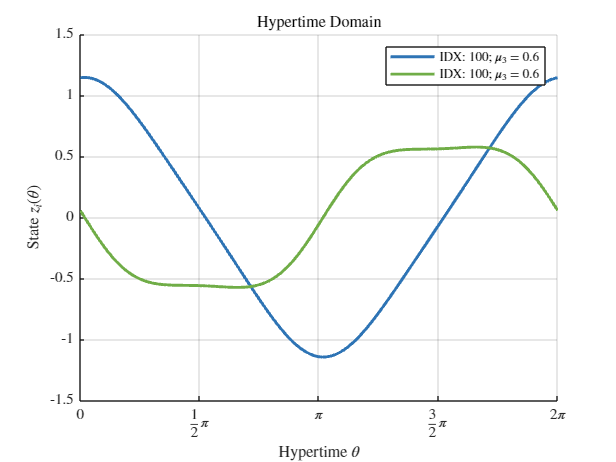

solplot_options_1 = costaropts('space','hypertime','zaxis','all','index',100);
[hypertime_val_solplot_1,z_val_solplot_1,mu_val_solplot_1,empty_solplot_1] = S.solplot(DYN,solplot_options_1);

As we selected the *hypertime* solution space and the solutions of our *Duffing* oscillator example are periodic, the solutions are shown for one period. Corresponding to the state vector, $x (\theta) = z_{\text{P},1} (\theta)$ is depicted as first (top) element of the legend, whereas $x' (\theta) = z_{\text{P},2} (\theta)$ is the second (bottom) element of the legend. As you may have noticed, the legend shows the index and the $\mu$-value of the depicted solution curve. The index $3$ of the $\mu$'s within the legend indicate that the continuation paramter $\mu$ is the third parameter within the `param` array or rather that we set `active_parameter = 3` (see section **Computing solutions to work with** above).

### Solutions parametrized in time (inlcuding trajectories)

In the last example, we depicted the solution curves in *hypertime* solution space. These solution curves are parametrized in *hypertime* solution space with respect to hypertime $\theta$. Now we want to have a look at the solution with respect to time $t$ and picture it for $t \in [0, 25]$. We focus on the first state variable $z_{\text{P},1} (t) = x (t)$ and compare the solution at index `100` with the solution at index `50` $(\mu = \eta \approx 0.39)$.

Therefore, we set the options field `'space'` to `'time'` and the field `'zaxis'` to` @(z)` `z(:,1)`. Furthermore, we define the field `'interval'` to plot the solutions for the desired time interval and increase the value of the resolution from default `200` to `500`. Since we want to display and compare the solutions at index `100` and index `50`, we set the field `'index'` to `[50,100]`.

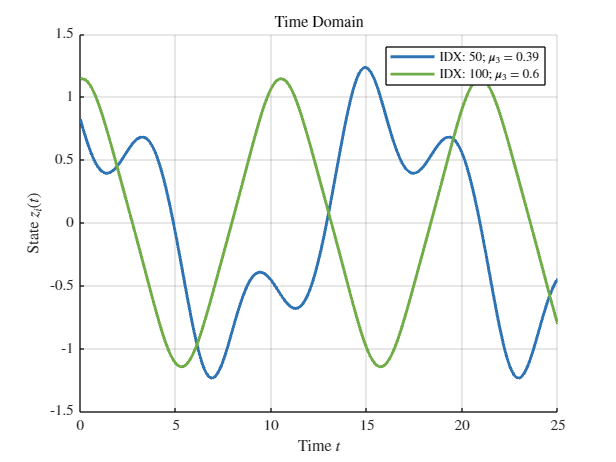

solplot_options_2 = costaropts('space','time','zaxis',@(z) z(:,1),'index',[50,100],'interval',[0,25],'resolution',500);
[t_val_solplot_2,z_val_solplot_2,mu_val_solplot_2,empty_solplot_2] = S.solplot(DYN,solplot_options_2);

Notice that the output arrays `t_val_solplot_2` and `z_val_solplot_2` are actually three-dimensional arrays now since two different solutions are displayed. Besides, the solution at index `100` shows almost 2.5 periods while the solution at index `50` only exhibits approximately 1.5 periods due to the underlying frequencies being different.

Apart from displaying the solutions with respect to time $t$, we want to depict the trajectories of the solutions in state space, which is also based on a parametrization in time. Thus, we set the options field `'space'` to `'trajectory'`. As usual for two-dimensional systems, we depict the first state variable $z_{\text{P},1} (t) = x (t)$ on the horizontal axis by setting `'xaxis'` to` @(z)` `z(:,1)` and the second state variable $z_{\text{P},2} (t) = x' (t)$ on the vertical axis by setting `'zaxis'` to` @(z)` `z(:,2)`. Furthermore, we plot both of the trajectories into the same figure and depict the solution at index `50` for $t \in [0, 12.5]$ as well as a red dashed line.

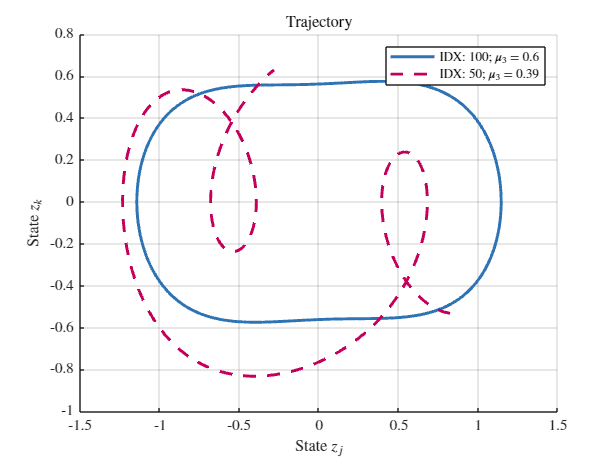

% Display the trajectory of the solution at index 100 for t in [0, 12.5]:
solplot_options_3 = costaropts('space','trajectory','xaxis',@(z) z(:,1),'zaxis',@(z) z(:,2),'index',100);
[x_val_solplot_3,z_val_solplot_3,mu_val_solplot_3,empty_solplot_3] = S.solplot(DYN,solplot_options_3);
% Display the trajectory of the solution at index 50 for t in [0, 12.5] in red and as a dashed line into the same figure:
solplot_options_4 = costaropts('space','trajectory','xaxis',@(z) z(:,1),'zaxis',@(z) z(:,2),'index',50,'interval',[0,12.5],...
                               'color','r','linestyle','--','figure',gcf);
[x_val_solplot_4,z_val_solplot_4,mu_val_solplot_4,empty_solplot_4] = S.solplot(DYN,solplot_options_4);

As you can see, the trajectory at index `100` is closed and therefore displayed for at least one period. In fact, this trajectory is displayed for exactly one period as we did not define an interval. The trajectory at index `50`, however, is "incomplete" since it exhibits a periodic time of $T_{50}=2\pi/\Omega_{50}\approx2\pi/0.39\approx16.1$. Thus, the defined time interval only covers roughly $78\%$ of the periodic orbit. 

### Frequency content of a solution

As a third example, we want to display the frequency content of the solutions at index `50` and at index `100`, so we set the options field `'space'` to `'frequency'`. Again, we focus on the first state variable $z_{\text{P},1} (t) = x (t)$ and thus set `'zaxis'` to` @(z)` `z(:,1)`. We do not set the field `'index'` to `[50,100]` this time because we treat each solution separately (the reason of why we do this should become clear after reading the next two paragraphs).

When computing the frequency content of a solution, a FFT (Fast-Fourier-Transformation) is carried out. It is important to note that the (angular) frequency resolution $\Delta\omega$ of the resulting frequency domain (the difference between two consecutive frequency values $\omega_{k+1}-\omega_k$ in the resulting plot / data) is inversely proportional to the duration $\tau$ of the input signal. The input signal is a computed solution in *time* solution space for $t \in [t_{\text{S}} \;\; t_{\text{E}}]$ and its duration $\tau$ can be set via the options field `'interval' (`$\tau \; = \;\; t_{\text{E}} - t_{\text{S}}$` = options.interval(2) - options.interval(1))`. In order to achieve a good frequency solution $\Delta\omega$, we set the upper limit of `'interval'` to $100\, T$ ($T$: period of the solution). However, this modification of `'interval'` drastically reduces the maximum frequency $\omega_{\text{max}}$ of the frequency domain (i.e. the maximal frequency that can be detected in the input signal), since $\omega_{\text{max}}$ is proportional $(\propto)$ to the sampling frequency $F_{\text{S}}$ and $F_{\text{S}} \, \propto r \, / \, \tau$ ( $r$: number of sampling points of the input signal), leading to $\omega_{\text{max}}$ being inversely proportional to $\tau$. To compensate for that, we can easily increase the number of sampling points $r$ by defining a high value for the field `'resolution'` ($r$ is the value of `'resolution'`). As the number of sampling points should be a power of $2$ for the FFT to be most efficient, we set the value of `'resolution'` to $r = 2^{13} = 8192$.

Moreover, we should consider that the input signal of the FFT is assumed to be periodic. If we took exactly 100 periods of a periodic input signal $x(t)$, i.e. $t \in [t_{\text{S}} \;\; t_{\text{E}}] = [0, 100T]$, and continue it periodically, we would obtain the time series $\left\lbrack \begin{array}{cccccccc}
x\left(0\right) & \cdots  & x\left(100T\right) & x\left(0\right) & \cdots  & x\left(100T\right) & x\left(0\right) & \cdots 
\end{array}\right\rbrack$. As you can see, this creates the problem that $x(0)$ follows $x(100T)$ directly, which does not make sense for periodic solutions in context of a time series. That is why the input signal of periodic solutions should only cover the time interval $t \in [t_{\text{S}} \;\; t_{\text{E}}] = [t_{\text{S}} \;\; (t_{\text{S}}+n \cdot T-\Delta t)]$ for the FFT to be most accurate, with $n \in \mathbb N$ and $\Delta t = t_{i+1} - t_i = n \cdot T \,/ \, r$ being the time step between two consecutive values of the time series. Thus, we first compute the periods $T_{50}$ and $T_{100}$ of the solutions at index `50` and at index `100`. The related angular frequencies can be taken from the `solution` object `S` via `S.freq(50)` and `S.freq(100)`. After that, we calculate the time steps $\Delta t_{50}$ and $\Delta t_{100}$ as well as the end times $t_{\text{E},50}$ and $t_{\text{E},100}$ of the intervals. Finally, we can call the `solplot` method and carry out a FFT of the solutions $x_{50} (t)$ and $x_{100} (t)$. It is done for each solution separately due to the different periods $T_{50}$ and $T_{100}$. CoSTAR then plots the absolute amplitudes $\vert \mathcal F (\omega) \vert$ for both of the two solutions with respect to the angular frequency $\omega$. The resulting frequency resolution $\Delta\omega_k$ $(k \in \lbrace{50, 100 \rbrace)$ can now be calculated from the sampling Frequency $F_{\text{S},k} = \frac{1}{\Delta t_k} = \frac{r}{n \cdot T_k} $ by $\Delta\omega_k = 2\pi \cdot \frac{F_{\text{S},k}}{r} = \frac{2\pi}{n \cdot T_k}$ and for the maximum frequency $\omega_{\text{max},k}$ of the frequency domain it follows $\omega_{\text{max},k} = 2\pi \left( \frac{F_{\text{S},k}}{2} - \frac{F_{\text{S},k}}{r} \right) = \pi \cdot F_{\text{S},k} - \Delta\omega_k = \frac{\pi}{n \cdot T_k} ( r - 2)$.

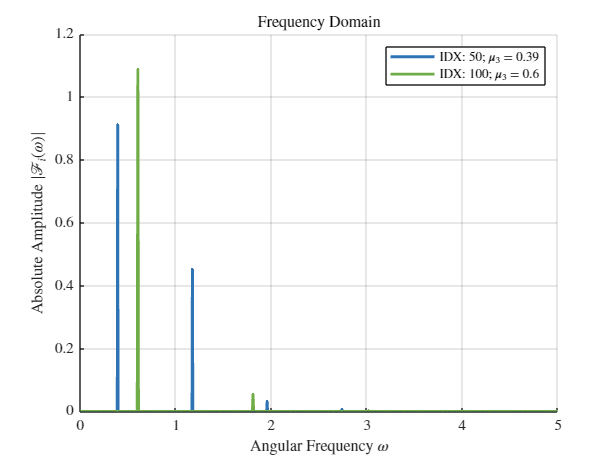

% Compute the end time of the intervals
res = 2^13;                                                                         % resolution
T_50 = 2*pi/S.freq(50);                 T_100 = 2*pi/S.freq(100);                   % periods of the solutions
Delta_t_50 = 100*T_50 / res;            Delta_t_100 = 100*T_100 / res;              % time steps between two consecutive points
int_end_50 = 100*T_50 - Delta_t_50;     int_end_100 = 100*T_100 - Delta_t_100;      % end time of the intervals
% FFT of the solution x(t) at index 50
solplot_options_5 = costaropts('space','frequency','zaxis',@(z) z(:,1),'index',50,'interval',[0 int_end_50],'resolution',res);
[omega_val_solplot_5,z_val_solplot_5,mu_val_solplot_5,empty_solplot_5] = S.solplot(DYN,solplot_options_5);
% FFT of the solution x(t) at index 100 and plot the results into the same figure
solplot_options_6 = costaropts('space','frequency','zaxis',@(z) z(:,1),'index',100,'interval',[0 int_end_100],'resolution',res,'figure',gcf);
[omega_val_solplot_6,z_val_solplot_6,mu_val_solplot_6,empty_solplot_6] = S.solplot(DYN,solplot_options_6);
% Adjust the limits of the frequency (horizontal) axis to see the interesting part of the frequency content more clearly
xlim([0 5])     

## Final Words

That's it! The CoSTAR tutorial on the postprocessing method `solplot` is now finished. Please keep in mind the `costarhelp` feature which you can use if you need a quick overview and a short description of the available options of `solplot`.

If you are interested in learning about further capabilities of CoSTAR, you are invited to have a look at the other tutorials as well.

See you soon!